# IMU Data Analysis

clear s
s = serialport("COM21", 9600)

s =   Serialport with properties:

                 Port: "COM21"
             BaudRate: 9600
    NumBytesAvailable: 0

  Show all properties, functions


data_length = 10;
frequency = 10;
time = 0:(1/frequency):data_length

time =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


yaw = zeros(1, data_length);
pitch = zeros(1, data_length);

for i = 1:data_length*frequency
    data = str2double(strip(s.readline()));
    if ~isnan(data)
        yaw(i) = data;
        pitch(i) = str2double(strip(s.readline()));
    else
        i = i - 1;
    end
end

save 01_28_2025.mat yaw pitch

yaw

yaw =          0  359.9375  359.9375  359.8750  359.6250  359.3750  359.1875  358.9375  358.8125  358.8125  358.8125  358.8125  358.7500  358.5625  358.3125  358.1250  357.9375  357.7500  357.6250  357.6250  357.6250  357.6250  359.0000    2.7500    7.2500   11.3125   15.8750   20.0000   24.1250   25.8750   25.8125   25.7500   25.6250   25.4375   25.3125   25.1875   25.1875   25.2500   25.3750   25.5000   25.6250   25.7500   25.8125   26.0000   26.1250   26.2500   26.3750   26.5000   26.6250   26.6875


pitch

pitch =          0   44.9375   44.9375   43.1250   39.1250   34.3125   29.9375   25.6250   23.5625   23.5625   23.5000   23.4375   21.9375   17.5000   13.2500    8.9375    4.2500         0   -1.7500   -1.8750   -2.0625   -2.1875   -2.3750   -2.6875   -3.0625   -3.3750   -3.7500   -4.0000   -4.3125   -4.4375   -6.1250  -10.0000  -14.5000  -18.6875  -22.8125  -24.5625  -24.5625  -22.6250  -18.5000  -14.1250   -9.3125   -4.8750   -0.5000    3.8125    8.6250   12.9375   17.3125   22.0625   26.3750   28.3750


yaw_velocity = diff(yaw)/(1/frequency)

yaw_velocity = 1.0e+03 *

    3.5994         0   -0.0006   -0.0025   -0.0025   -0.0019   -0.0025   -0.0013         0         0         0   -0.0006   -0.0019   -0.0025   -0.0019   -0.0019   -0.0019   -0.0013         0         0         0    0.0138   -3.5625    0.0450    0.0406    0.0456    0.0413    0.0413    0.0175   -0.0006   -0.0006   -0.0013   -0.0019   -0.0013   -0.0013         0    0.0006    0.0013    0.0013    0.0013    0.0013    0.0006    0.0019    0.0013    0.0013    0.0013    0.0013    0.0013    0.0006    0.0119


pitch_velocity = diff(pitch)/(1/frequency)

pitch_velocity =   449.3750         0  -18.1250  -40.0000  -48.1250  -43.7500  -43.1250  -20.6250         0   -0.6250   -0.6250  -15.0000  -44.3750  -42.5000  -43.1250  -46.8750  -42.5000  -17.5000   -1.2500   -1.8750   -1.2500   -1.8750   -3.1250   -3.7500   -3.1250   -3.7500   -2.5000   -3.1250   -1.2500  -16.8750  -38.7500  -45.0000  -41.8750  -41.2500  -17.5000         0   19.3750   41.2500   43.7500   48.1250   44.3750   43.7500   43.1250   48.1250   43.1250   43.7500   47.5000   43.1250   20.0000   -0.6250


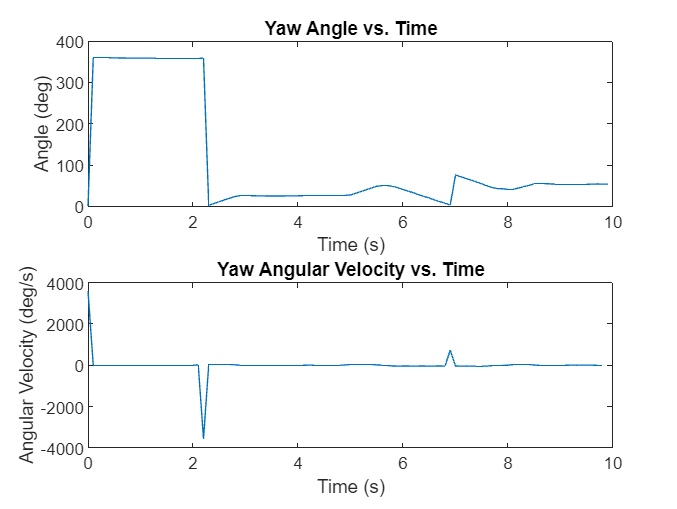


subplot(2,1,1)
plot(time(1:data_length*frequency), yaw)
title("Yaw Angle vs. Time")
xlabel("Time (s)")
ylabel("Angle (deg)")

subplot(2,1,2)
plot(time(1:data_length*frequency-1), yaw_velocity)
title("Yaw Angular Velocity vs. Time")
xlabel("Time (s)")
ylabel("Angular Velocity (deg/s)")

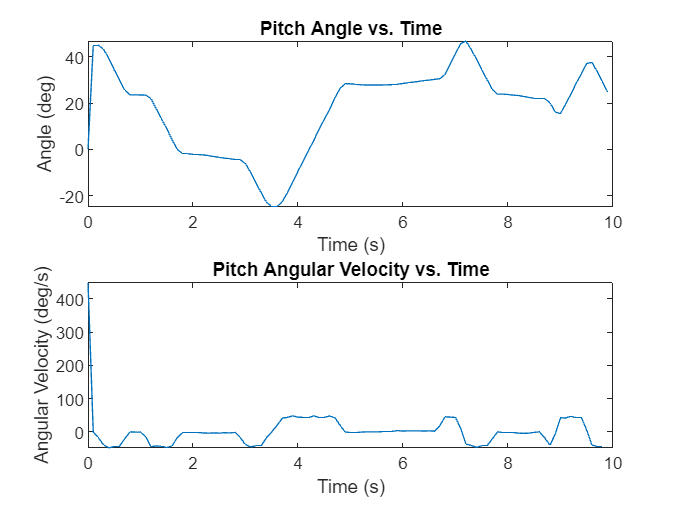

subplot(2,1,1)
plot(time(1:data_length*frequency), pitch)
title("Pitch Angle vs. Time")
xlabel("Time (s)")
ylabel("Angle (deg)")

subplot(2,1,2)
plot(time(1:data_length*frequency-1), pitch_velocity)
title("Pitch Angular Velocity vs. Time")
xlabel("Time (s)")
ylabel("Angular Velocity (deg/s)")